[speech, Fs] = audioread('./Data_assignment_5/speech1_10k.wav');

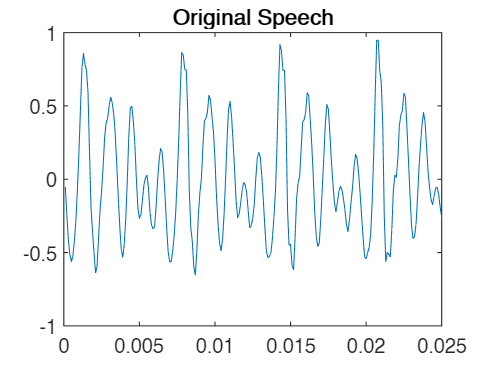

range = (1:length(speech))/Fs;
plot(range, speech);
title('Original Speech');

window_duration = 0.025;
shift_duration = 0.015;
window = hamming(window_duration*Fs);
shift = shift_duration*Fs;

% Adjusting and padding speech to window
w_speech = zeros(1, length(window) * ...
    ceil(length(speech)/length(window)));
w_speech(1:length(speech)) = speech;
speech = w_speech;

num_shifts = ceil((length(speech) - length(window))/shift);
num_windows = num_shifts+1;

windowed_speech = zeros(num_windows, length(window));
for i=0:num_windows-1
    windowed_speech(i+1, :) = ...
    speech(i*shift+1:(i*shift)+length(window)) .* window';
end

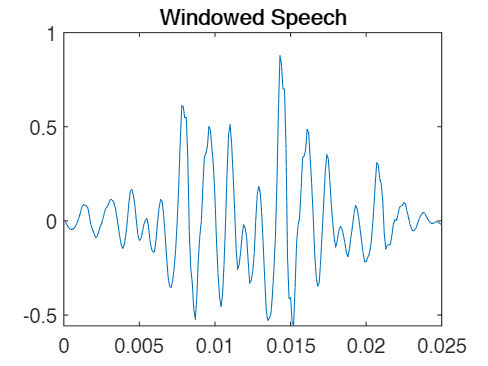

range_win = (1:length(window))/Fs;
% hold on;
for i=1:num_windows
%     figure;
    plot(range_win+(i-1)*window_duration, windowed_speech(i, :));
%     title('Window ', i);
end
title('Windowed Speech')

% hold off;

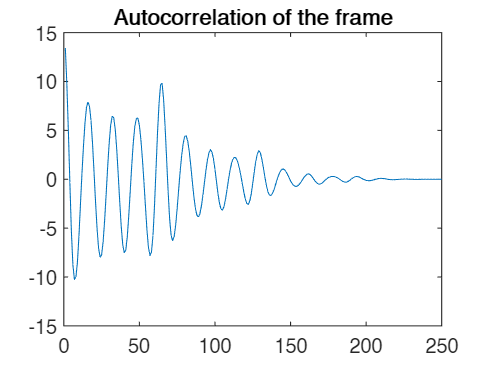

% plot((1:length(window))/Fs, windowed_speech(1, :));

window_autocorr = Autocorrelation(windowed_speech(1, :));
figure;
plot(window_autocorr);
title('Autocorrelation of the frame')

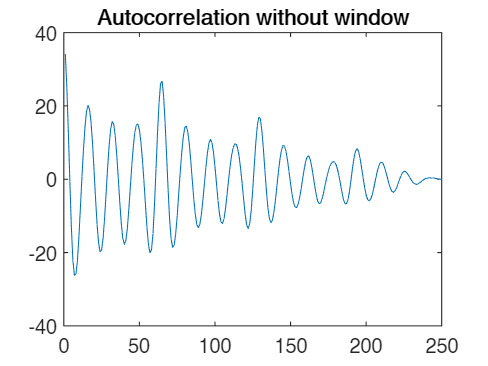

normal_autocorr = Autocorrelation(speech);
figure;
plot(normal_autocorr);
title('Autocorrelation without window')

% Calculating Autocorrelation matrix
acf = conv(speech, fliplr(conj(speech)));
Rxx = acf(length(speech):end);
Rx=toeplitz(Rxx,[Rxx(1) conj(Rxx(2:end))])

Rx =    37.8238   34.1825   24.9962   12.8619   -0.6114  -13.1957  -22.0984  -26.1518  -25.9367  -22.2319  -15.6593   -7.4801    0.7042    8.0711   14.2417   18.4631   20.1070   19.1086   15.5654    9.7534    2.4383   -5.2924  -12.2772  -17.3872  -19.8096  -19.2763  -15.9800  -10.4511   -3.6296    3.2889    9.3115   13.6808   15.7116   15.0584   11.9001    6.7762    0.4787   -6.0932  -11.9591  -16.0523  -17.6953  -16.7930  -13.4896   -8.3045   -2.2087    3.8526    9.0927   12.8462   14.8296   15.0486
   34.1825   37.8238   34.1825   24.9962   12.8619   -0.6114  -13.1957  -22.0984  -26.1518  -25.9367  -22.2319  -15.6593   -7.4801    0.7042    8.0711   14.2417   18.4631   20.1070   19.1086   15.5654    9.7534    2.4383   -5.2924  -12.2772  -17.3872  -19.8096  -19.2763  -15.9800  -10.4511   -3.6296    3.2889    9.3115   13.6808   15.7116   15.0584   11.9001    6.7762    0.4787   -6.0932  -11.9591  -16.0523  -17.6953  -16.7930  -13.4896   -8.3045   -2.2087    3.8526    9.0927   12.8462   1